Workspace of Delta Robot

clear
clc

Px = linspace(-0.5,0.5);
Py = linspace(-0.5,0.5);
Pz = linspace(0.2,0.8);
possible_ws = zeros(1,3,1000000);
i = 1;

for z = Pz
    for y = Py
        for x = Px
            possible_ws(1,:,i) = analytic_linear_delta_robot_ik_ws([x y z]);
            i = i+1;
        end
    end
end


possible_ws_2 = possible_ws;
possible_ws_2 = reshape(possible_ws_2,3,size(possible_ws_2,3))';
possible_ws(:,:,all(isnan(possible_ws),2)) = [];
size(possible_ws,3)

ans = 196180

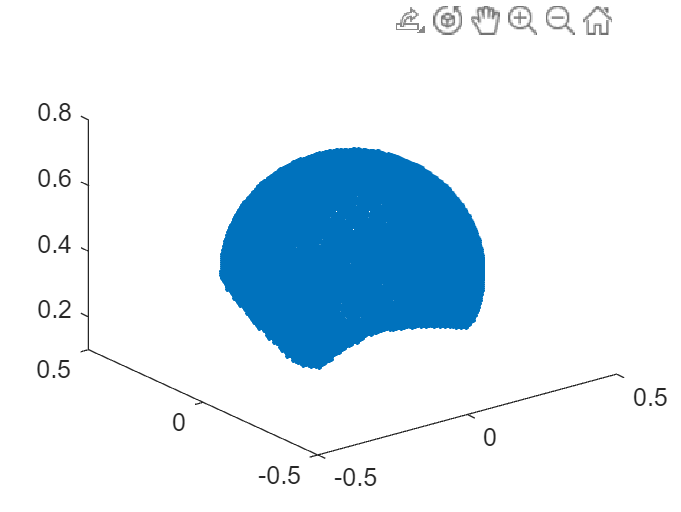

possible_ws = reshape(possible_ws,3,size(possible_ws,3))';
% plot3(possible_ws(:,1),possible_ws(:,2),possible_ws(:,3),'.')
k = boundary(possible_ws(:,1),possible_ws(:,2),possible_ws(:,3),1);
plot3(possible_ws(k,1),possible_ws(k,2),possible_ws(k,3),'.')
xlim([-0.50 0.50])
ylim([-0.50 0.50])
zlim([0.1 0.80])

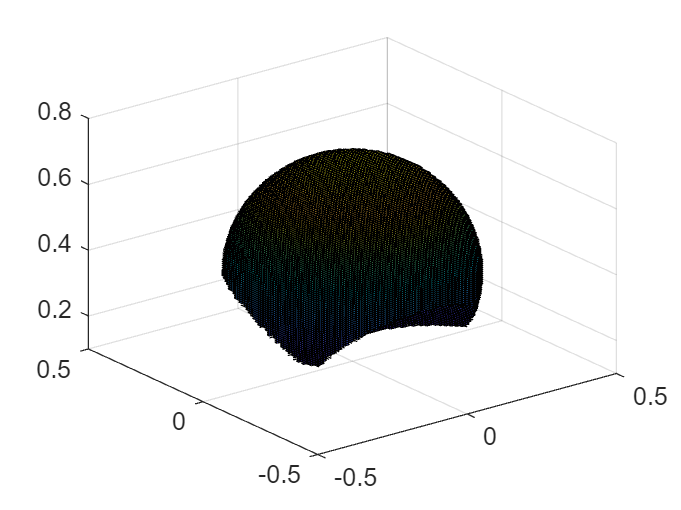


x_pos_ws = reshape(possible_ws_2(:,1),100,10000)';
y_pos_ws = reshape(possible_ws_2(:,2),100,10000)';
z_pos_ws = reshape(possible_ws_2(:,3),100,10000)';
surf(x_pos_ws,y_pos_ws,z_pos_ws)
xlim([-0.50 0.50])
ylim([-0.50 0.50])
zlim([0.1 0.80])

function available_eePos = analytic_linear_delta_robot_ik_ws(eePosDes)
    R = 0.45;
    r = 0.04;
    a = R*(sqrt(3)/2);
    b = pi/4;
    h = 0.35;
    d = r*(sqrt(3)/2);
    based_plate_thick = R/15;
    bottom_plate_thick = r/15;
    eeL = 0.03;

    eePosOri = eePosDes;
    eePosDes(3) = eePosDes(3)-bottom_plate_thick/2-eeL+based_plate_thick/2;
    
    Q1 = eePosDes(2)-d+a;
    G11 = Q1^2+eePosDes(1)^2+eePosDes(3)^2-h^2;
    G12 = -2*eePosDes(3)*sin(b)-2*Q1*cos(b);
    l1p = (-G12+sqrt(G12^2-4*G11))/2;
    l1n = (-G12-sqrt(G12^2-4*G11))/2;
    
    Q21 = eePosDes(1)+(sqrt(3)/2)*(a-d);
    Q22 = eePosDes(2)+(d-a)/2;
    G21 = Q21^2+Q22^2+eePosDes(3)^2-h^2;
    G22 = -sqrt(3)*Q21*cos(b)+Q22*cos(b)-2*eePosDes(3)*sin(b);
    l2p = (-G22+sqrt(G22^2-4*G21))/2;
    l2n = (-G22-sqrt(G22^2-4*G21))/2;
    
    Q31 = eePosDes(1)+(sqrt(3)/2)*(d-a);
    Q32 = eePosDes(2)+(d-a)/2;
    G31 = Q31^2+Q32^2+eePosDes(3)^2-h^2;
    G32 = sqrt(3)*Q31*cos(b)+Q32*cos(b)-2*eePosDes(3)*sin(b);
    l3p = (-G32+sqrt(G32^2-4*G31))/2;
    l3n = (-G32-sqrt(G32^2-4*G31))/2;

    lp = [l1p l2p l3p]';
    ln = [l1n l2n l3n]';

    if ~isreal(lp) || ~isreal(ln)
        available_eePos = NaN(1,3);
    elseif all(ln>=0) && all(ln<=0.5)
        available_eePos = eePosOri;
    elseif all(lp>=0) && all(lp<=0.5)
        available_eePos = eePosOri;
    else
        available_eePos = NaN(1,3);
    end
end